# Validación Controlador

addpath("sims\")
simout = sim("plantaClosedLoopPID.slx"); % simluacion no lineal 
load("dataExperimental-pid.mat");


t = simout.tout; 
y_nl = simout.nl_response.Data;

tLoL = linspace(expT2(end),15,10)';
y2LoL = expY2(end)*ones(10,1);

expT2 = [expT2; tLoL]

expT2 =     0.0060
    0.0110
    0.0150
    0.0200
    0.0240
    0.0290
    0.0330
    0.0380
    0.0440
    0.0480


expY2 = [expY2; y2LoL]

expY2 =    11.0742
   11.2500
   11.4258
   11.5137
   11.6016
   11.7773
   11.7773
   11.8652
   11.8652
   11.9531


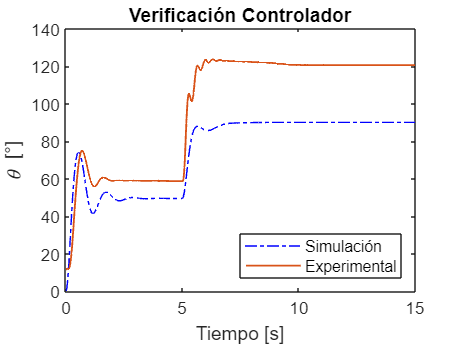


figure()
plot(t,y_nl,"b-.");
hold on
plot(expT2,expY2,"LineWidth",1);
xlim([0,15])
title('Verificación Controlador')
xlabel('Tiempo [s]')
ylabel('\theta [°]')
legend('Simulación','Experimental','Location','southeast')


expT2(end)

ans = 15